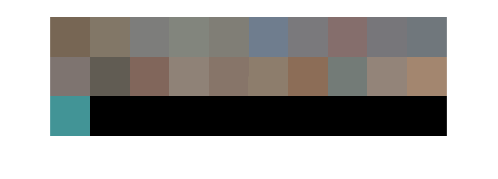

clear
clf

folder = './data';
fileList = dir(fullfile(folder, '*.jpg'));

images = cell(1, numel(fileList));
resized_images = cell(1, numel(fileList));
blocksize = 64;

avg_colors = zeros(numel(fileList), 3);  % Matrix to store average colors (R, G, B)

for i = 1:numel(fileList)
    filename = fullfile(folder, fileList(i).name);
    images{i} = im2double(imread(filename));
    resized_images{i} = imresize(images{i}, [blocksize, blocksize]);
    
    % Calculate average color for each channel (R, G, B)
    avg_colors(i, 1) = mean(mean(resized_images{i}(:,:,1)));  % Red channel
    avg_colors(i, 2) = mean(mean(resized_images{i}(:,:,2)));  % Green channel
    avg_colors(i, 3) = mean(mean(resized_images{i}(:,:,3)));  % Blue channel
end
showRGB(avg_colors)

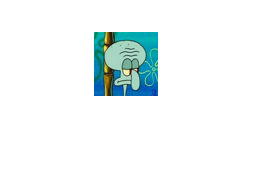

imshow(resized_images{21});